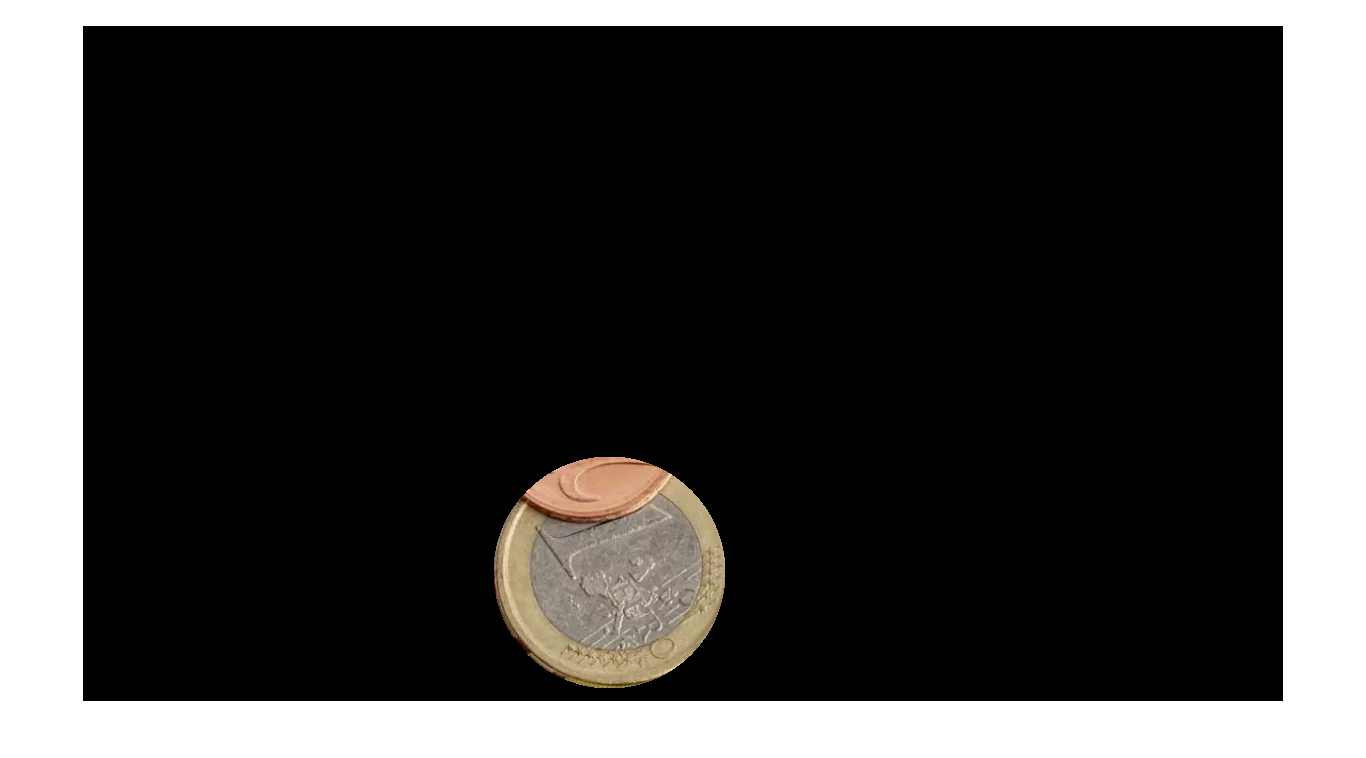

Error using imageDisplayValidateParams
Expected input number 1, I, to be one of these types:

double, single, uint8, uint16, uint32, uint64, int8, int16, int32, int64, logical

Instead its type was cell.

Error in images.internal.imageDisplayValidateParams (line 11)
validateattributes(common_args.CData, {'numeric','logical'},...

Error in 

radiusPadding = 0;
IOrig = imread("muenzenVerdeckung.jpg");
cut(radiusPadding, IOrig);

function y = cut(radiusPadding, IOrig)
    imshow(IOrig);
    
    d = drawline;
    pos = d.Position;
    diffPos = diff(pos);
    diameter = round(hypot(diffPos(1), diffPos(2)));
    
    [centers, radii] = imfindcircles(IOrig, [round(diameter * 0.25), diameter], ...
        "EdgeThreshold", 0.25, "Sensitivity", 0.97);
    viscircles(centers, radii);
    
    coinCount = size(centers, 1);

    imagesize = size(IOrig);

    cellStorage = cell(coinCount, 6);
    cellStorage(:,6) = num2cell(0);
    
    for i = 1:coinCount
        x = round(centers(i, 1));
        y = round(centers(i, 2));
        r = round(radii(i)) + radiusPadding;

        [xx, yy ] = ndgrid((1:imagesize(1))-y,(1:imagesize(2))-x);

        mask = uint8((xx.^2 + yy.^2)<(r^2));
        IMasked(:,:,:) = IOrig(:,:,:).*mask;
        imshow(IMasked)
        
        %imwrite("CutCoins/img_%02d.jpg", IMasked);

        ICoin = imcrop(IMasked, [x - r, y - r, 2 * r , 2* r ]);
        ICoin = imresize(ICoin, [256, 256]);
    
        str = sprintf("readCoins/img_%02d.jpg",i);
        imwrite(ICoin, str);

        cellStorage(i, 1) = num2cell(i);
        cellStorage(i, 2) = cellstr(str);
        cellStorage(i, 3) = num2cell(x);
        cellStorage(i, 4) = num2cell(y);
        cellStorage(i, 5) = num2cell(round(radii(i)));
    
    end
    y = cellStorage;
end